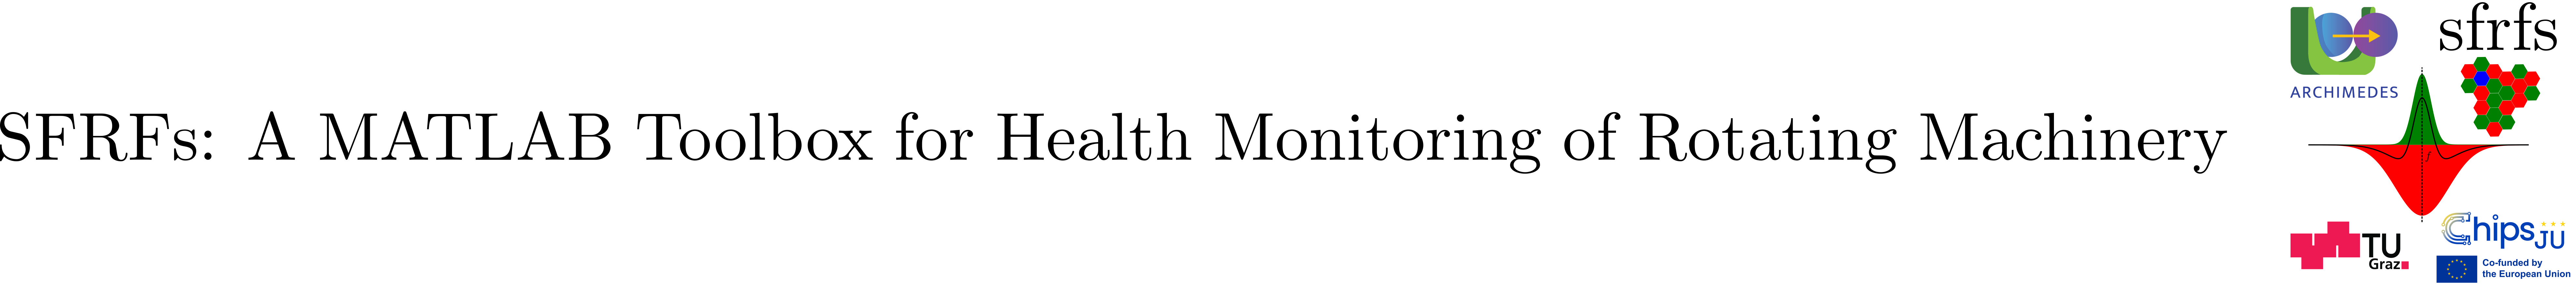

# `LiftedHarmonicGainFunctions`

## Summary

`LiftedHarmonicGainFunctions` is a handle class that computes harmonic-indexed center-surround spectral gain functions for a specified characteristic frequency. It preserves individual harmonic receptive fields rather than aggregating their frequency bands into a single mask.

**Key features:**

- Constructs center and surround spectral masks for selected harmonics of a characteristic frequency.

- Preserves individual harmonic indices and center frequencies.

- Supports Gaussian and super-Gaussian mask parameterizations through the existing SFRF parameters.

- Uses the frequency domain defined by `ParametersSnapshot`.

- Produces a structured table containing harmonic metadata, frequency bands, and corresponding spectral masks.

- Separates spectral mask construction from receptive-field response computation.

The class provides a computational realization of a harmonic specialization of the Indexed Spectral Probe Family [ISPF] defined in the SFRFs formal framework [2].

## Description

`LiftedHarmonicGainFunctions` computes harmonic-indexed spectral gain functions for Spectral Fault Receptive Fields (SFRFs). Given a characteristic frequency, a selection of harmonic indices, and the corresponding SFRF parameters, the class constructs center and surround frequency masks over the frequency domain defined by `ParametersSnapshot`.

For each selected harmonic, the class determines its center frequency and associated center and surround bands. The corresponding masks are evaluated using the configured mask parameterizations and stored in `liftedGainFunctionsTable`, together with the harmonic indices, center frequencies, and frequency-band information.

Unlike `ReceptiveFieldGainFunctions`, which combines multiple frequency bands into consolidated receptive-field masks, this class preserves the individual harmonic components. This representation enables harmonic-resolved spectral analysis and subsequent evaluation of center-surround responses through `LiftedHarmonicResponseCompute`.

The class implements the spectral probe construction stage only. It does not evaluate receptive-field responses, compute contrast, or perform spectral amplitude normalization. Its harmonic-indexed construction corresponds to a specialization of the Indexed Spectral Probe Family [ISPF] in the formal SFRFs framework [2].

**See also:**  [ReceptiveFieldGainFunctions](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [LiftedHarmonicResponseCompute](matlab:open('./LiftedHarmonicResponseCompute.mlx')), [`FrequencyMask`](matlab:open('./FrequencyMask.mlx')), [`ParametersSnapshot`](matlab:open('./ParametersSnapshot.mlx')), [`SFRFsParametersRollingBearings`](matlab:open('./SFRFsParametersRollingBearings.mlx'))

### **Public properties**

### Constructor

#### LiftedHarmonicGainFunctions

Constructs a harmonic-indexed spectral gain function object for a specified characteristic frequency, fault type, and operating condition.

The constructor validates the supplied parameters and resolves the harmonic indices against the usable frequency support. If no harmonic indices are provided, all admissible positive harmonic indices are selected automatically.

**Syntax**

`lhgf = LiftedHarmonicGainFunctions( ...`

`    snapshotParameters=sp, ...`

`    sfrfsParameters=sfrfsParams, ...`

`    faultType=faultType, ...`

`    selection=selection, ...`

`    characteristicFrequencyHz=fc, ...`

`    harmonicIndices=h);`

The `harmonicIndices` argument is optional.

**Parameters**

**Output**

Returns a `LiftedHarmonicGainFunctions` handle object. The constructor initializes its configuration and resolves the harmonic indices but does not compute the spectral masks. Call `compute()` to populate `liftedGainFunctionsTable`.

### Public methods

#### compute

Computes harmonic-indexed center and surround spectral gain functions for the selected characteristic frequency and harmonic indices.

For each harmonic, the method determines the center frequency and corresponding center and surround frequency bands. The masks are evaluated over the frequency domain supplied by `ParametersSnapshot`, using the configured SFRF mask parameters. Individual harmonic masks are preserved without aggregation.

**Syntax**

`lhgf.compute()`

**Parameters**

This method does not accept additional parameters. It uses the configuration established during construction.

**Output**

The method does not return a value. The computed results are stored in the `liftedGainFunctionsTable` property, and the frequency grid is stored in `frequencyDomain`.

Each row of `liftedGainFunctionsTable` represents one harmonic and contains:

#### computeMaxHarmonicIndex

Computes the maximum admissible harmonic index for a specified characteristic frequency and snapshot frequency domain.

The method accounts for the Nyquist frequency and the available positive-frequency support. It returns the smaller of the frequency-based and spectral-support-based limits.

**Syntax**

`maxHarmonic = LiftedHarmonicGainFunctions.computeMaxHarmonicIndex( ...`

`    snapshotParameters=sp, ...`

`    characteristicFrequencyHz=fc);`

**Parameters**

**Output**

The method raises an error if no harmonic lies within the usable frequency support.

## Example

This example illustrates the construction of harmonic-indexed center and surround spectral gain functions for a selected bearing fault. The characteristic frequency is specified explicitly to illustrate the harmonic construction independently of bearing geometry. Each harmonic retains its own spectral masks rather than contributing to an aggregated receptive field.

### Harmonic-indexed gain functions computation

First, we define the snapshot parameters and the center–surround mask configuration. We then select an outer-race fault, an operating condition, and three harmonics of a characteristic frequency of 100 Hz.

% Configuration
% Define snapshot parameters
sp = ParametersSnapshot( ...
    samplingFrequency = 1024, ...
    duration = 1, ...
    stride = 1);

% Define shared SFRF parameters
sharedParams = SFRFsParameters.buildSFRFsParameters( ...
    order = 0, ...
    numSidebands = 0, ...
    numHarmonics = 3, ...
    centerMask = SuperGaussianMaskParameters( ...
    alpha = 2, ...
    beta = 8), ...
    surroundMask = SuperGaussianMaskParameters( ...
    alpha = 6, ...
    beta = 2), ...
    inhibitionFactor = 0.9);

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

% Select fault type and operating condition
ft = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;

sel = OperatingConditionSelection( ...
    speed = 35, ...
    load = 12);

% Define characteristic frequency and harmonic indices
fc = 100;
h = [1; 2; 3];

Next, we construct the harmonic-indexed gain functions object and compute its frequency-domain masks. The resulting table contains one row per harmonic, including its center frequency, center and surround bands, and corresponding masks.

% Construct harmonic-indexed gain functions
lhgf = LiftedHarmonicGainFunctions( ...
    snapshotParameters = sp, ...
    sfrfsParameters = sfrfsParams, ...
    faultType = ft, ...
    selection = sel, ...
    characteristicFrequencyHz = fc, ...
    harmonicIndices = h);

% Compute spectral masks
lhgf.compute();

% Inspect results
gainTable = lhgf.liftedGainFunctionsTable;
disp(gainTable);

     FaultType     HarmonicIndex    CenterFrequencyHz    CenterBandHz    SurroundBandHz    FrequencyBankMasks
    ___________    _____________    _________________    ____________    ______________    __________________

    "outerRace"          1                 100           {[ 98 102]}      {[ 94 106]}         {1×1 struct}   
    "outerRace"          2                 200           {[198 202]}      {[194 206]}         {1×1 struct}   
    "outerRace"          3                 300           {[298 302]}      {[294 306]}         {1×1 struct}   



The table should contain three rows, corresponding to harmonics 1, 2, and 3, centered at 100, 200, and 300 Hz, respectively.

### Visualizing the harmonic gain functions

We can visualize the individual spectral masks to inspect their center–surround organization. Solid lines represent center masks, while dashed lines represent surround masks. Each harmonic is displayed independently.

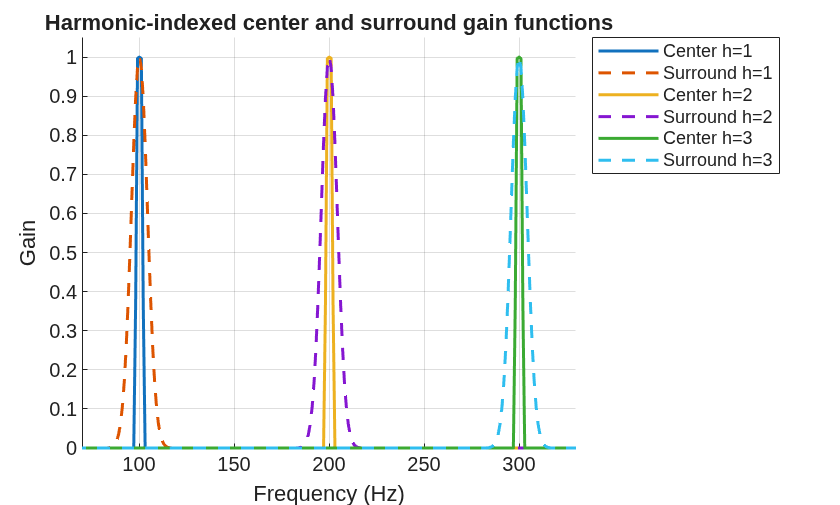

f = lhgf.frequencyDomain;

figure;
hold on;

for i = 1:height(gainTable)
    masks = gainTable.FrequencyBankMasks{i};

    plot(f, masks.CenterMask, ...
        'LineWidth', 1.5, ...
        'DisplayName', sprintf('Center h=%d', ...
        gainTable.HarmonicIndex(i)));

    plot(f, masks.SurroundMask, '--', ...
        'LineWidth', 1.5, ...
        'DisplayName', sprintf('Surround h=%d', ...
        gainTable.HarmonicIndex(i)));
end

xlabel('Frequency (Hz)');
ylabel('Gain');
title('Harmonic-indexed center and surround gain functions');

xlim([70 330]);
ylim([0 1.05]);
grid on;
legend('show', 'Location', 'bestoutside');
hold off;

The visualization shows three distinct harmonic receptive fields. For each harmonic, the narrow center mask is surrounded by a broader spectral mask. Unlike the aggregated gain functions produced by `ReceptiveFieldGainFunctions`, these masks remain individually accessible for subsequent harmonic-resolved response computation.

## API documentation

### MATLAB **help**

The MATLAB `help` command displays the class documentation extracted from its source file.

help LiftedHarmonicGainFunctions

 LiftedHarmonicGainFunctions
 
  Builds center/surround mask banks for selected harmonics of one
  characteristic frequency.

    Documentation for LiftedHarmonicGainFunctions



**MATLAB ****documentation**

The MATLAB `doc` command opens the corresponding documentation in the MATLAB Help Browser.

doc LiftedHarmonicGainFunctions

## Source code

The source code of this class can be found in [`LiftedHarmonicGainFunctions`](matlab:open('../../LiftedHarmonicGainFunctions.m')).

edit LiftedHarmonicGainFunctions

## Test

Unit testing for the class is implemented in `TestLiftedHarmonicGainFunctions`.

Execute the tests

res = runtests('tests/TestLiftedHarmonicGainFunctions.m');

Setting up ProjectFixture
Done setting up ProjectFixture: Project 'sfrfs-toolbox' is already loaded. Setup is not required.
__________

Running TestLiftedHarmonicGainFunctions
.......... .....
Done TestLiftedHarmonicGainFunctions
__________

Tearing down ProjectFixture
Done tearing down ProjectFixture: Teardown is not required.
__________



SFRFsTestUtil.printTestSummary(res, 80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestLiftedHarmonicGainFunctions/testValidConstruction                            | Passed
TestLiftedHarmonicGainFunctions/testComputeCreatesTable                          | Passed
TestLiftedHarmonicGainFunctions/testHarmonicFrequenciesAreCorrect                | Passed
TestLiftedHarmonicGainFunctions/testMasksHaveFrequencyDomainSize                 | Passed
TestLiftedHarmonicGainFunctions/testMasksAreBounded                              | Passed
TestLiftedHarmonicGainFunctions/testCenterAndSurroundBandsUseAlphas              | Passed
TestLiftedHarmonicGainFunctions/testSelectedHarmonicsArePreserved                | Passed
TestLiftedHarmonicGainFunctions/testFrequencyDomainIsStored                      | Passed
TestLiftedHarmonicGainFunctions/testNegativeCharacteristicFrequencyThrows        | Passed
TestLifted

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). *SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery*. Zenodo. [DOI: 10.5281/zenodo.17631784](https://doi.org/10.5281/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Stan Muñoz Gutiérrez and Franz Wotawa. *A Formal Framework for Spectral Fault Receptive Fields (with Examples for Bearing Health Monitoring).* Technical Report TR-SFRFs-v1.0.1, Institute of Software Engineering and Artificial Intelligence, Graz University of Technology, Graz, Austria (2026).